# Tether Conclusions 

The following MATLAB Live Script includes the exhaustive individual plots for a total of 30 experiments perfomed on the orange 4-limbed robot on the black mat. 

% Dependencies:
%   +demos/data/visualtracking
%   +offlineanalysis/GaitTest
%   +gaitdef/Gait

% [0] == Script setup
clear; clc; close all

% Add dependencies to classpath
addpath('../');
addpath('data/visualtracking');

% Configure figure tex interpreters
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultTextInterpreter','latex');
set(0, 'DefaultAxesFontSize', 18);

## Extract and define parameters for GaitTest() objects.

#### From 20220707 Experiments:

    *Gait B-120     *[heavy - not following (restting) - left/up]

gait_names{1}  = 'B_120_H_NF_L.mat';   

    *Gait E-120     *[heavy - not following - left/up]

gait_names{2}  = 'E_120_H_NF_L.mat';   

    *Gait E-60     *[heavy - not following - left/up] 

gait_names{3}  = 'E_60_H_NF_L.mat';    

    *Gait E*-60     *[heavy - not following - right/up]  Caution! Not real E gait! Limb A not actuating

gait_names{4}  = 'Es_60_H_NF_R.mat';   

#### From 20220819 Experiments:

    *Gait B-120    * [light sheath - not following (restting) - right/up]

gait_names{5}  = 'B_120_S_NF_R.mat';   

#### From 20220829 Experiments:

*    Gait B* Follow (Left)     *[light sheath - following - left]  Caution! Not real B gait! Limb A not actuating

gait_names{6}  = 'Bs_60_S_F_L.mat'; 

*    Gait B* Follow (Right)     *[light sheath - following - right]  Caution! Not real B gait! Limb A not actuating

gait_names{7}  = 'Bs_60_S_F_R.mat';  

    *Gait E Left (sheath on)*     [light sheath - not following - left]

gait_names{8}  = 'E_60_S_NF_L.mat';    

   * Gait E Right (sheath on)    * [no sheath - not following - right]

gait_names{9}  = 'E_60_S_NF_R.mat';    

*    Gait E Left (sheath off)    * [no sheath - not following - left]

gait_names{10} = 'E_60_NS_NF_L.mat';   

    *Gait E* Right (sheath off)*     [no sheath - not following - right] Caution! Not real E gait! Limb B not actuating

gait_names{11} = 'Es_60_NS_NF_R.mat';  

#### From 20220901 Experiments:

    *Gait E Left (sheath off)*      [no sheath - not following - left (flipped)]

gait_names{12} = 'E_60_NS_NF_Lf.mat'; 

    *Gait B Follow (Left) Trial 1*      [light sheath - following - left]

gait_names{13} = 'B_60_S_F_L.mat';     

    *Gait B Follow (Left) Trial 2*     [light sheath - following - left (flipped)]

gait_names{14} = 'B_60_S_F_Lf.mat';    

*    Gait B Left (Sheath on) Trial 1*     [light sheath - not following - left]

gait_names{15} = 'B_60_S_NF_L.mat';    

    *Gait B Left (Sheath on) Trial 2 *    [light sheath - not following - left (flipped)]

gait_names{16} = 'B_60_S_NF_Lf.mat';   

#### From 20220908 Experiments:

    *Gait B Right (sheath on)*      [sheath - not following - right] (not consistent / semi-following)

gait_names{17} = 'B_60_S_NF_R.mat';    

   * Gait B Right Follow (sheath off) Trial 1*      [no sheath - following - right]

gait_names{18} = 'B_60_NS_F_R.mat';   

*    Gait B Right Follow (sheath off) Trial 2 *    [no sheath - following - right]

gait_names{19} = 'B_60_NS_F_R_2.mat'; 

    *Gait B Left Follow (sheath off) Trial 1*     [no sheath - following - left]

gait_names{20} = 'B_60_NS_F_L.mat'; 

    *Gait B Left Follow (sheath off) Trial 2*     [no sheath - following - left]

gait_names{21} = 'B_60_NS_F_L_2.mat';  

     *Gait B Right (sheath off) Trial 1*     [no sheath -  not following - right] (not consistent / semi-following)

gait_names{22} = 'B_60_NS_NF_R.mat'; 

    *Gait B Right (sheath off) Trial 2*     [no sheath -  not following - right] (not consistent / semi-following)

gait_names{23} = 'B_60_NS_NF_R_2.mat'; 

     *Gait B Left (sheath off) Trial 1*     [no sheath -  not following - left] (not consistent / semi-following)

gait_names{24} = 'B_60_NS_NF_L.mat';  

    *Gait B Left (sheath off) Trial 2*     [no sheath -  not following - left] (not consistent / semi-following)

gait_names{25} = 'B_60_NS_NF_L_2.mat';

     *Gait B Right Follow (sheath on) *     [sheath - following - right] 

gait_names{26} = 'B_60_S_F_R.mat';   

    *Gait E Right (sheath off) Trial 1*    [no sheath -  not following - right] (not consistent / semi-following)

gait_names{27} = 'E_60_NS_NF_R.mat';   

    *Gait E Right (sheath off) Trial 2 *    [no sheath -  not following - right] (not consistent / semi-following)

gait_names{28} = 'E_60_NS_NF_R_2.mat'; 

    *Gait E Left (sheath off) Trial 1 *    [no sheath -  not following - left] (not consistent / semi-following)

gait_names{29} = 'E_60_NS_NF_L_2.mat'; 

    *Gait E Left (sheath off) Trial 2 *    [no sheath -  not following - left] (not consistent / semi-following)

gait_names{30} = 'E_60_NS_NF_L_3.mat';   

#### From 20220928 Experiments:

    *Gait B Left AWG 32 Trial 1*      [AWG 32 sheath - not following - left] 

gait_names{31} = 'B_60_32_NF_L_1.mat';    

   * Gait B Left AWG 32 Trial 2*      [AWG 32 sheath - not following - left] 

gait_names{32} = 'B_60_32_NF_L_2.mat';   

*    Gait B Right AWG 32 Trial 1*    [AWG 32 sheath - not following - right] 

gait_names{33} = 'B_60_32_NF_R_1.mat'; 

*    Gait B Right AWG 32 Trial 2*    [AWG 32 sheath - not following - right] 

gait_names{34} = 'B_60_32_NF_R_2.mat'; 

*    Gait B Right AWG 32 Trial 1*    [AWG 32 slip ring - not following - right] 

%gait_names{35} = 'B_60_32SR1_NF_R_1.mat'; 
% tracking data was corrupted

*    Gait B Right AWG 32 Trial 2*    [AWG 32 slip ring - not following - right] 

gait_names{35} = 'B_60_32SR1_NF_R_2.mat'; 
% Note: old slip ring design

#### From 20221018 Experiments:

    *Gait F Left AWG 32 Slip ring Trial 1*      [AWG 32 slip ring - not following - left] 

gait_names{36} = 'F_60_32SR_NF_L_1.mat';    

   * Gait F Left AWG 32 Slip ring Trial 2*      [AWG 32 slip ring - not following - left] 

gait_names{37} = 'F_60_32SR_NF_L_2.mat';   

*    Gait G Left AWG 32 Slip ring Trial 1*    [AWG 32 slip ring - not following - left] 

gait_names{38} = 'G_60_32SR_NF_L_1.mat'; 

*    Gait G Left AWG 32 Slip ring Trial 2*    [AWG 32 slip ring - not following - left] 

gait_names{39} = 'G_60_32SR_NF_L_2.mat'; 

#### From 20221102 Experiments: 

*    Gait G Right AWG 32 Slip ring Trial 1*    [AWG 32 slip ring - not following - right] 

gait_names{40} = 'G_60_32SR_NF_R_1.mat'; 

*    Gait G Right AWG 32 Slip ring Trial 2*    [AWG 32 slip ring - not following - right] 

gait_names{41} = 'G_60_32SR_NF_R_2.mat'; 

*    Gait B Left AWG 32 Slip ring Trial 1*    [AWG 32 slip ring - not following - left] 

gait_names{42} = 'B_60_32SR_NF_L_1.mat'; 

*    Gait B Right AWG 32 Slip ring Trial 1*    [AWG 32 slip ring - not following - right] 

gait_names{43} = 'B_60_32SR_NF_R_1.mat'; 

*    Gait H Left AWG 32 Slip ring Trial 1*    [AWG 32 slip ring - not following - left] 

gait_names{44} = 'H_60_32SR_NF_L_1.mat'; 

*    Gait H Left AWG 32 Slip ring Trial 2*    [AWG 32 slip ring - not following - left] 

gait_names{45} = 'H_60_32SR_NF_L_2.mat'; 

*    Gait H Right AWG 32 Slip ring Trial 1*    [AWG 32 slip ring - not following - right] 

gait_names{46} = 'H_60_32SR_NF_R_1.mat'; 

*    Gait H Right AWG 32 Slip ring Trial 2*    [AWG 32 slip ring - not following - right] 

gait_names{47} = 'H_60_32SR_NF_R_2.mat'; 

    *Gait F Right AWG 32 Slip ring Trial 1*      [AWG 32 slip ring - not following - right] 

gait_names{48} = 'F_60_32SR_NF_R_1.mat';    

   * Gait F Right AWG 32 Slip ring Trial 2*      [AWG 32 slip ring - not following - right] 

gait_names{49} = 'F_60_32SR_NF_R_2.mat'; 

### Build Experiment Matrix

if isrow(gait_names)
    gait_names = gait_names';
end
n_gaits = length(gait_names);

% Extract characteristics of each gait test.
file_names = split(gait_names, '.');
gait_characteristics = cell(n_gaits, 7);
for i = 1:n_gaits
    gait_characteristics(i, 1) = num2cell(i);
    n_underscores = count(gait_names{i}, '_');
    if n_underscores == 4
        gait_characteristics(i, 2:6) = split(file_names(i,1), '_');
        gait_characteristics(i, 7) = num2cell(1);
    else
        gait_characteristics(i, 2:7) = split(file_names(i,1), '_');
    end
end
characteristics = ["Experiment", "Gait", "#Cycles", "Tether", ...
              "Protocol", "Placement", "Trial"];
% Build table.
experiments = cell2table(gait_characteristics, "VariableNames", ...
              characteristics);
sorted_exps = sortrows(experiments, characteristics([2, 4, 5, 6, 7]))

sorted_exps = 49×7 table
    Experiment    Gait     #Cycles     Tether      Protocol    Placement    Trial
    __________    _____    _______    _________    ________    _________    _____

        31        {'B'}    {'60' }    {'32'   }     {'NF'}       {'L'}        1  
        32        {'B'}    {'60' }    {'32'   }     {'NF'}       {'L'}        2  
        33        {'B'}    {'60' }    {'32'   }     {'NF'}       {'R'}        1  
        34        {'B'}    {'60' }    {'32'   }     {'NF'}       {'R'}        2  
        42        {'B'}    {'60' }    {'32SR' }     {'NF'}       {'L'}        1  
        43        {'B'}    {'60' }    {'32SR' }     {'NF'}       {'R'}        1  
        35        {'B'}    {'60' }    {'32SR1'}     {'NF'}       {'R'}        2 

% Construct titles. 
title_components = string(gait_characteristics);
title_components(strcmp(experiments.Tether, 'H'), 4) = 'heavy sheath';
title_components(strcmp(experiments.Tether, 'S'), 4) = 'light sheath';
title_components(strcmp(experiments.Tether, 'NS'), 4) = 'no sheath';
title_components(strcmp(experiments.Tether, '32'), 4) = '32 AWG';
title_components(strcmp(experiments.Tether, '32SR'), 4) = '32 AWG with slip ring';
title_components(strcmp(experiments.Protocol, 'F'), 5) = 'following';
title_components(strcmp(experiments.Protocol, 'NF'), 5) = 'not following';
title_components(strcmp(experiments.Placement, 'L'), 6) = 'left';
title_components(strcmp(experiments.Placement, 'R'), 6) = 'right';
title_components = [repmat(["Experiment" ":" "cycles of Gait" "with" "tether (" "," ")," "trial"], n_gaits, 1) title_components];
title_matrix = title_components(:, [1,9,2,11,3,10,4,12,5,14,6,13,7,8,15]);
exp_title = join(title_matrix);
% Define experimental parameters after investigating videos. 
frame_start_list(1:4) = [382, 234, 141, 109];
frame_start_list(5) = 76;
frame_start_list(6:11) = [210, 168, 131, 131, 55, 983];
frame_start_list(12:16) = [132, 184, 278, 324, 196];
frame_start_list(17:25) = [63, 45, 39, 49, 137, 36, 63, 39, 519];
frame_start_list(26:30) = [88, 51, 64, 50, 57];
frame_start_list(31:35) = [25,50,49,45,45];
frame_start_list(36:39) = [21,25,24,18];
frame_start_list(40:49) = [44,32,32,36,32,33,30,25,31,21];

% Find marker order by investigating first frame.
marker_order_list = repmat([1 3 4 2],n_gaits, 1);
marker_order_list([2,3,43],:) = repmat([1 4 3 2],3,1);
marker_order_list([8,9,10,21,25,31,34,40,41,44],:) = repmat([2 4 3 1],10,1);
marker_order_list([12,14,16],:) = repmat([4 2 1 3],3,1);
marker_order_list([26, 35,46,47],:) = repmat([2,3,4,1],4,1);

show_markers = true;     % plots first frame of each video

% Initialize the stability experiment struct. 
stab_exp = struct('params', [], 'raw_data', []);
gait_sequences = cell(n_gaits,1);

% Extract data.
for i = 1:n_gaits
    % Define robot / experiment parameters.
    stab_exp(i).params.robot_name = 'orange';
    stab_exp(i).params.substrate = 'black mat';
    stab_exp(i).params.n_markers = 4;
    stab_exp(i).params.pixel_length = 1/8.6343;     % cm per pixel

    % Define number of gait cycles run.
    if ismember(i,[1,2,5])
        stab_exp(i).params.n_cycles= 119; 
         % accounts for pause after first cycle in some of the videos
    else
        stab_exp(i).params.n_cycles= 59;
    end

    % Extract and store first frame information.
    stab_exp(i).params.frame_1 = frame_start_list(i);
    stab_exp(i).params.marker_order = marker_order_list(i,:);
    
    % Extract and store raw data from each trial
    filename = gait_names{i};
    stab_exp(i).raw_data = load(filename).tracking_data;  
    if experiments.Gait{i} == 'B'
        gait_sequences{i} = [16,7,5,11,14];   % Gait B (rotational)
    elseif experiments.Gait{i} == 'E'
        gait_sequences{i} = [9,16,1];         % Gait E (translational)
    elseif experiments.Gait{i} == 'Bs'
        gait_sequences{i} = [8,7,5,3,6];
    elseif experiments.Gait{i} == 'Es' 
        gait_sequences{i} = [9,12,1];
     elseif experiments.Gait{i} == 'F'
        gait_sequences{i} = [9 14 8 1];
    elseif experiments.Gait{i} == 'G' 
        gait_sequences{i} = [3 15 1];
    elseif experiments.Gait{i} == 'H'
        gait_sequences{i} = [7 12 13 2];
    else
        gait_sequences{i} = [];
    end
    gait_sequences{4} = [1, 16, 1];
end

## Analyze the experiment data:

#### 1. Rotate the data w.r.t. the initial global orientation.

% Define first experiment first frame orientation as theta = 0. 
markers_x(1, :) = stab_exp(1).raw_data(1, 1:3:stab_exp(1).params.n_markers*3-2);
markers_y(1, :) = stab_exp(1).raw_data(1, 2:3:stab_exp(1).params.n_markers*3-1);
centroid(:, :, 1) = mean([markers_x(1, :); markers_y(1, :)], 2);
% Move initial position to (0,0) origin.
reference_markers = [markers_x(1, [1 3 4 2]); markers_y(1, [1 3 4 2]);]...
                    - centroid(:, :, 1);
% For each trial, rotate data to align first frame global orientations.
 for i = 1:n_gaits
    % Find initial rotation matrix for each trial to have consistent fixed frame.
    markers_x(i, :) = stab_exp(i).raw_data(1, 1:3:stab_exp(i).params.n_markers*3-2);
    markers_y(i, :) = stab_exp(i).raw_data(1, 2:3:stab_exp(i).params.n_markers*3-1);
    centroid(:, :, i) = mean([markers_x(i, :); markers_y(i, :)], 2);

    % Move initial position to (0,0) origin.
    shifted_markers = [markers_x(i, stab_exp(i).params.marker_order);
                       markers_y(i, stab_exp(i).params.marker_order)]...
                       - centroid(:, :, i);

    % Find orientation of subsequent trials w.r.t. first trial GCS.
    [regParams,~,~] = absor(reference_markers, shifted_markers);
    stab_exp(i).params.R_1 = [regParams.R zeros(2,1); 0 0 1];
 end


#### 2. Instantiate GaitTest() objects for each experimental trial.

 %This analyzes the data from each trial to find motion primitive twist information.
% Instantiate objects for each gait tested. 
all_gaits = offlineanalysis.GaitTest.empty(0,n_gaits); 
gait_defs = gaitdef.Gait.empty(0,n_gaits);
tail_idx = cell(n_gaits, 1);
head_idx = cell(n_gaits, 1);
delta_poses = cell(n_gaits,1);
global_theta = cell(n_gaits,1);
twists = cell(n_gaits,1);
cent_rot = cell(n_gaits,1);
rad_curv = cell(n_gaits,1);

#### 3. Calculate twists for each gait experiment.

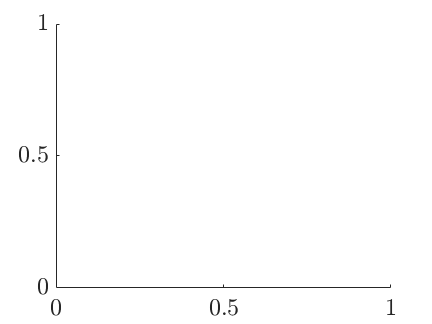

% Calculate twists for each gait experiment.
for i = 1:n_gaits
    all_gaits(i) = offlineanalysis.GaitTest(stab_exp(i).raw_data, ...
                                                 gait_sequences{i}(1,:), ...
                                                 stab_exp(i).params);
    gait_defs(i) = gaitdef.Gait(all_gaits(i), stab_exp(i).params);
    % Manually find the twists. 
    % Extract gait / experiment details. 
    n_cycles = all_gaits(i).n_cycles;
    len_gait = all_gaits(i).len_gait;
     for j = 1:n_cycles - 1
         % Record indexes for each motion primitive tail and head. 
         tail_idx{i}(1,j) = all_gaits(i).keyframes(len_gait*(j-1)+2);
         head_idx{i}(1,j) = all_gaits(i).keyframes(len_gait*j+2);

         % Find change in poses w.r.t. global inertial frame for each motion primitive. 
         delta_poses{i}(:,j) = all_gaits(i).raw_poses(:, head_idx{i}(1,j)) - all_gaits(i).raw_poses(:, tail_idx{i}(1,j));
         delta_poses{i}(1:2,j) = all_gaits(i).pixel_length*delta_poses{i}(1:2,j);

         % Find global orientation of robot at each motion primitive tail. 
         global_theta{i}(:,j) = all_gaits(i).raw_poses(3, tail_idx{i}(1,j));

         % Convert from global frame to body frame.  
         rot_mat =  [cos(global_theta{i}(1,j)) -sin(global_theta{i}(1,j)); sin(global_theta{i}(1,j)) cos(global_theta{i}(1,j))];
         delta_poses{i}(1:2,j) = rot_mat'*delta_poses{i}(1:2,j);
         R =  [cos(delta_poses{i}(3,j)) -sin(delta_poses{i}(3,j)); sin(delta_poses{i}(3,j)) cos(delta_poses{i}(3,j))];
         % Convert to twists.
         twists{i}(:,j)  = gait_defs(i).delta_pose_2_twist(delta_poses{i}(:,j), all_gaits(i).transition_time*len_gait);

         % Find instantaneous center of rotation.
         cent_rot{i}(:,j) = (eye(2) - R)\delta_poses{i}(1:2, j);

         % Find instantaneous radius of curvature.
         rad_curv{i}(1,j) = norm(cent_rot{i}(:,j));
     end
     
end

figure
hold on

for i = [20,22,36,37,38,39]
    %all_gaits(i).plot;
end
T_array = table2array(sorted_exps(:,1))

T_array =     31
    32
    33
    34
    42
    43
    35
     1
    20
    21


for i = 1:n_gaits
    disp(exp_title(T_array))
end

    "Experiment 31 : 60 cycles of Gait B with 32 AWG tether ( left , not following ), trial 1"
    "Experiment 32 : 60 cycles of Gait B with 32 AWG tether ( left , not following ), trial 2"
    "Experiment 33 : 60 cycles of Gait B with 32 AWG tether ( right , not following ), trial 1"
    "Experiment 34 : 60 cycles of Gait B with 32 AWG tether ( right , not following ), trial 2"
    "Experiment 42 : 60 cycles of Gait B with 32 AWG with slip ring tether ( left , not following ), trial 1"
    "Experiment 43 : 60 cycles of Gait B with 32 AWG with slip ring tether ( right , not following ), trial 1"
    "Experiment 35 : 60 cycles of Gait B with 32SR1 tether ( right , not following ), trial 2"
    "Experiment 1 : 120 cycles of Gait B with heavy sheath tether ( left , not following ), trial 1"
    "Experiment 20 : 60 cycles of Gait B with no sheath tether ( left , following ), trial 1"
    "Experiment 21 : 60 cycles of Gait B with no sheath tether ( left , following ), trial 2"
    "Experime

writematrix(exp_title(T_array), 'titles.xlsx')

## Make exhaustive plots for each experiment. 

Experiment 36 : 60 cycles of Gait F with 32 AWG with slip ring tether ( left , not following ), trial 1


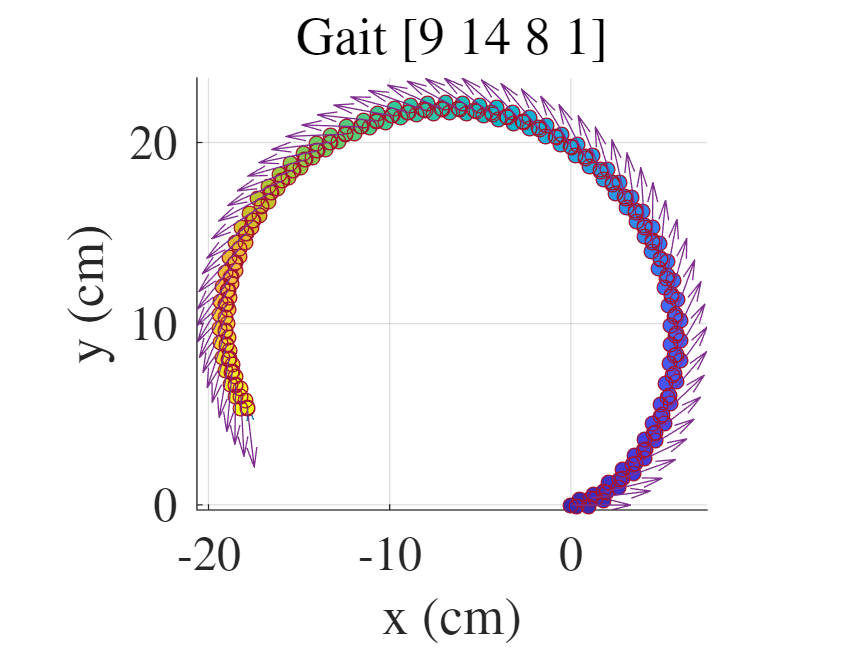

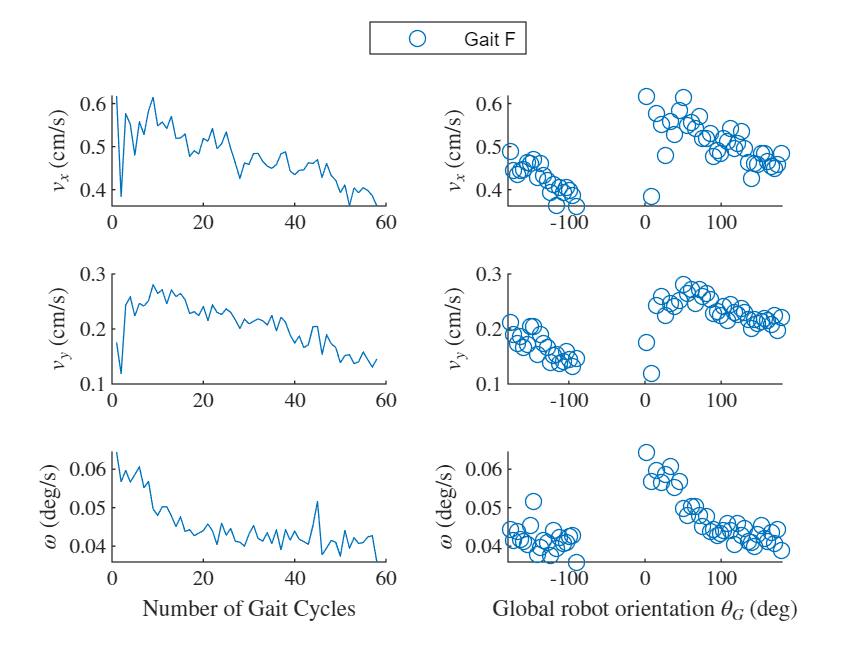

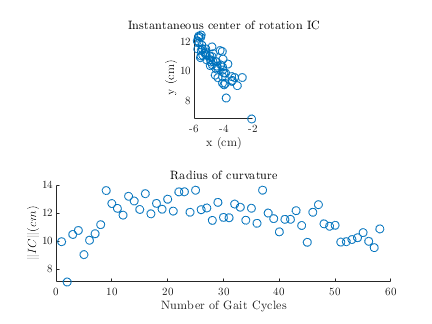

for i = 36
    disp(exp_title(i))
    figure
    all_gaits(i).plot;
    figure
    plot_twists(twists, global_theta, i, ['Gait ', experiments.Gait{i}], []);
    figure
    tiledlayout(2,1)
    nexttile
    scatter(cent_rot{i}(1,:), cent_rot{i}(2,:))
    xlabel('x (cm)')
    ylabel('y (cm)')
    title('Instantaneous center of rotation IC')
    daspect([1 1 1]);
    nexttile
    scatter(1:length(rad_curv{i}(1,:)), rad_curv{i}(1,:))
    title('Radius of curvature')
    xlabel('Number of Gait Cycles')
    ylabel('$\| IC\|  (cm)$')
end

## Make gait libraries.

% Gait B ( no sheath ).
gait_library_3(1) = gaitdef.Gait(all_gaits([18,19,20,21,22,25]));
gait_library_3(1).robot_name = 'orange';
gait_library_3(1).tether = 'no sheath';
gait_library_3(1).tether_protocol = {'F (right)','F (right)', 'F (left)', 'F (left)', 'NF (right)', 'NF (left)'};
gait_library_3(1).gait_name = 'B';
% Gait F ( no sheath, slip ring ).
gait_library_3(2) = gaitdef.Gait(all_gaits([36,37]));
gait_library_3(2).robot_name = 'orange';
gait_library_3(2).tether = 'no sheath with slip ring';
gait_library_3(2).tether_protocol = {'NF (left)','NF (left)'};
gait_library_3(2).gait_name = 'F';
% Gait G ( no sheath, slip ring ).
gait_library_3(3) = gaitdef.Gait(all_gaits([38,39]));
gait_library_3(3).robot_name = 'orange';
gait_library_3(3).tether = 'no sheath with slip ring';
gait_library_3(2).tether_protocol = {'NF (left)','NF (left)'};
gait_library_3(3).gait_name = 'G';

## Plot gait libraries.

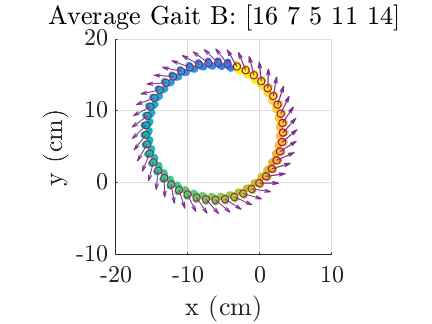

figure 
gait_library_3(1).plot(60);
title("Average Gait B" + ": [" +num2str(gait_library_3(1).robo_states) + "]")

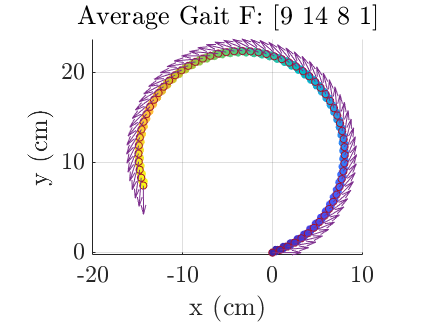

figure
gait_library_3(2).plot(60);
title("Average Gait F" + ": [" +num2str(gait_library_3(2).robo_states) + "]")

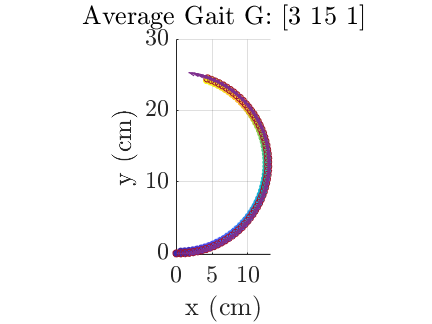

figure
gait_library_3(3).plot(60);
title("Average Gait G" + ": [" +num2str(gait_library_3(3).robo_states) + "]")

%save data/gait_library_3 gait_library_3

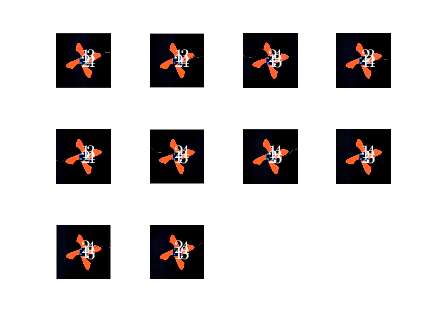


if show_markers
    figure
    %tiledlayout(5,6)
    tiledlayout(3,4)
    for i = 40:49
    
    pic_name = gait_names{i};
    pic_name(end-3:end) = [];
    % Plot first image of experiment video.
    file_name = ['data/visualtracking/firstframe_', pic_name, '.jpg'];
    pic = imread(file_name);
    nexttile;
    imshow(pic)
    hold on
    
    % Plot labeled (i.e., numbered) markers on top of image.
    markers_x(i, :) = stab_exp(i).raw_data(1, 1:3:stab_exp(i).params.n_markers*3-2);
    markers_y(i, :) = stab_exp(i).raw_data(1, 2:3:stab_exp(i).params.n_markers*3-1);
%     if iTrial ~=5
    for m = 1:stab_exp(i).params.n_markers
        text(markers_x(i, m), 1080-markers_y(i, m), num2str(m),'Color','white','FontSize',14);
%     end
    end
    
    % Adjust size.
     xlim([min(markers_x(i, :))-200, max(markers_x(i, :))+200]);
     ylim([min(1080 - markers_y(i, :)) - 200, max(1080 - markers_y(i, :))+200]);
    
    
end
end

function twists_plot = plot_twists(twists, global_theta, trial_nums, trial_labels, ylims)

    twists_plot = tiledlayout(3,2);
    ylabels = {'$v_x$ (cm/s)', '$v_y$ (cm/s)', '$\omega$ (deg/s)'};

    % Plot twist components vs number of gait cycles.
    for i = 1:3
        nexttile(2*i - 1);
        hold on;
        for j = 1:length(trial_nums)        
            plot(twists{trial_nums(j)}(i,:))
        end
        ylabel(ylabels{i})
        if ~isempty(ylims)
            ylim(ylims(i,:))
        end
    end
    xlabel('Number of Gait Cycles')
    
    % Plot twist components vs global robot orientation.
    for i = 1:3
        nexttile(2*i);
        hold on;
        for j = 1:length(trial_nums)        
            scatter(rad2deg(global_theta{trial_nums(j)}(1,:)),twists{trial_nums(j)}(i,:))
        end
        xlim([-180 180])
        ylabel(ylabels{i})
        if ~isempty(ylims)
            ylim(ylims(3+i,:))
        end
    end
    xlabel('Global robot orientation $\theta_G$ (deg)')

    if length(trial_labels) > 1
        lgd = legend(trial_labels);
        lgd.Orientation = 'horizontal';
        lgd.Layout.Tile = 'north';
    else
        plot_title = ['Twist (body velocity) for', trial_labels];
        title(twists_plot,plot_title, 'FontSize',22) 
    end
end